%%Read csv data
data_sku = readmatrix("../data/markov_regression_train_479.csv")

data_sku = 1.0e+03 *

    2.0200    0.0020    0.0030         0    0.0010    0.9450    0.0060    0.0010
    2.0190    0.0110    0.0100    0.0010         0    0.6500   -0.6500    0.0500
    2.0200    0.0030    0.0040         0    0.0010    0.9450    0.0060    0.0030
    2.0200    0.0090    0.0180         0    0.0010    0.9450    0.0020    0.0090
    2.0210    0.0010    0.0120    0.0010    0.0010    0.7500    0.0020    0.0160
    2.0210    0.0080    0.0270    0.0010    0.0010    0.8000    0.0020    0.0380
    2.0210    0.0070    0.0120    0.0010    0.0010    0.8500    0.0020    0.0040
    2.0200    0.0080    0.0030    0.0010    0.0010    0.8500    0.0020    0.0040
    2.0200    0.0030    0.0180    0.0010    0.0010    0.7300    0.0010    0.0010
    2.0190    0.0100    0.0090    0.0010         0    0.7500   -0.7500    0.0020


size(data_sku)

ans =         1065           8


%% Chnage to date
ad_t = datetime(data_sku(:,1),data_sku(:,2),data_sku(:,3))

ad_t = 1065×1 datetime array
   03-Feb-2020
   10-Nov-2019
   04-Mar-2020
   18-Sep-2020
   12-Jan-2021
   27-Aug-2021
   12-Jul-2021
   03-Aug-2020
   18-Mar-2020
   09-Oct-2019
   25-Dec-2019
   19-Apr-2020
   19-Oct-2020
   05-Apr-2022
   17-Sep-2019
   20-Jun-2021
   18-Oct-2019
   03-Sep-2019
   11-Jul-2020
   12-Feb-2022
   11-Jun-2021
   11-Dec-2021
   10-Dec-2020
   13-Mar-2022
   04-Oct-2021
   14-Apr-2022
   27-Mar-2020
   26-Aug-2020
   04-May-2020
   05-Jun-2022


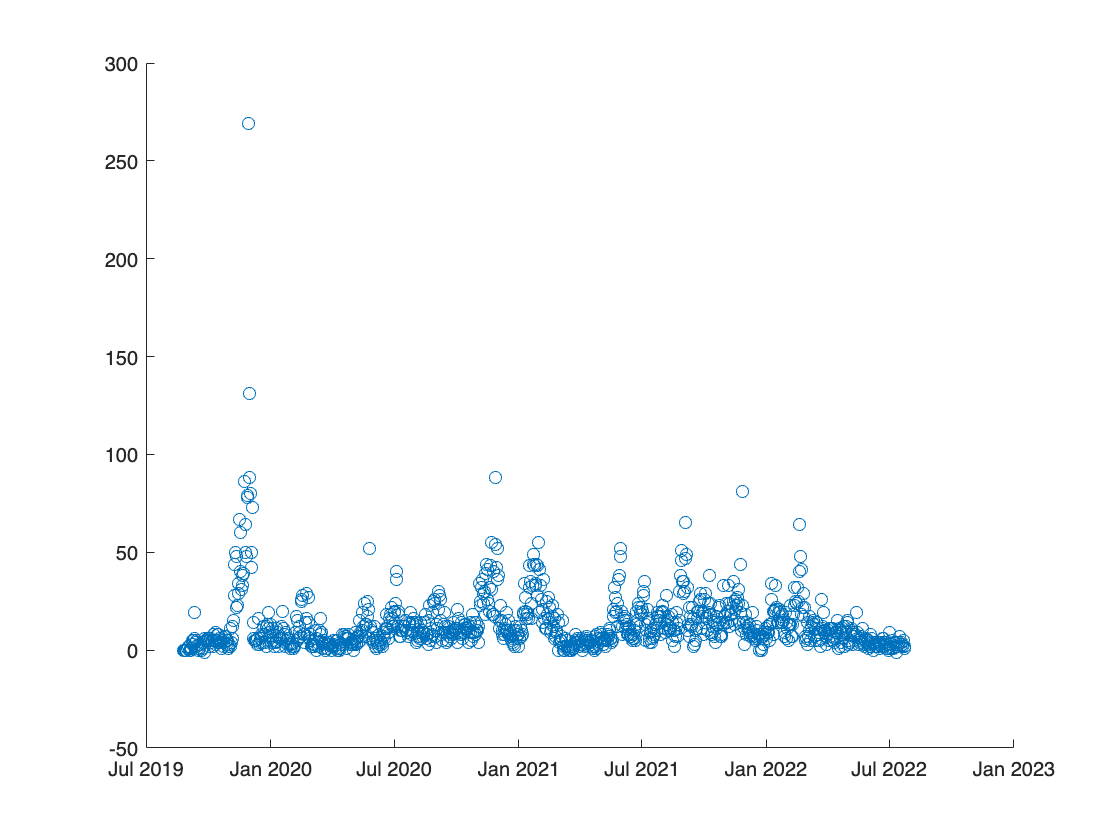


% Plot data and overlay NBER recession bands:
figure
scatter(ad_t,data_sku(:,8))

## Initialise ARIMA models

 mdl10 = arima('AR',[0.2 -0.3 0.5],'MA',[0.1 0.2 0.3],'Constant',1, ...
     'Beta',[1 2 3 4], "Seasonality",365)

mdl10 =   arima with properties:

     Description: "ARIMAX(3,0,3) Model Seasonally Integrated (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 368
               D: 0
               Q: 3
        Constant: 1
              AR: {0.2 -0.3 0.5} at lags [1 2 3]
             SAR: {}
              MA: {0.1 0.2 0.3} at lags [1 2 3]
             SMA: {}
     Seasonality: 365
            Beta: [1 2 3 4]
        Variance: NaN


 mdl20 = arima('AR',[0.2 -0.3 0.5],'MA',[0.1 0.2 0.3],'Constant',1, ...
     'Beta',[1 2 3 4], "Seasonality",30)

mdl20 =   arima with properties:

     Description: "ARIMAX(3,0,3) Model Seasonally Integrated (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 33
               D: 0
               Q: 3
        Constant: 1
              AR: {0.2 -0.3 0.5} at lags [1 2 3]
             SAR: {}
              MA: {0.1 0.2 0.3} at lags [1 2 3]
             SMA: {}
     Seasonality: 30
            Beta: [1 2 3 4]
        Variance: NaN

## Initialise Markov Chain

mc0 = dtmc([0.5 0.5; 0.5 0.5]);

## Estimate Model

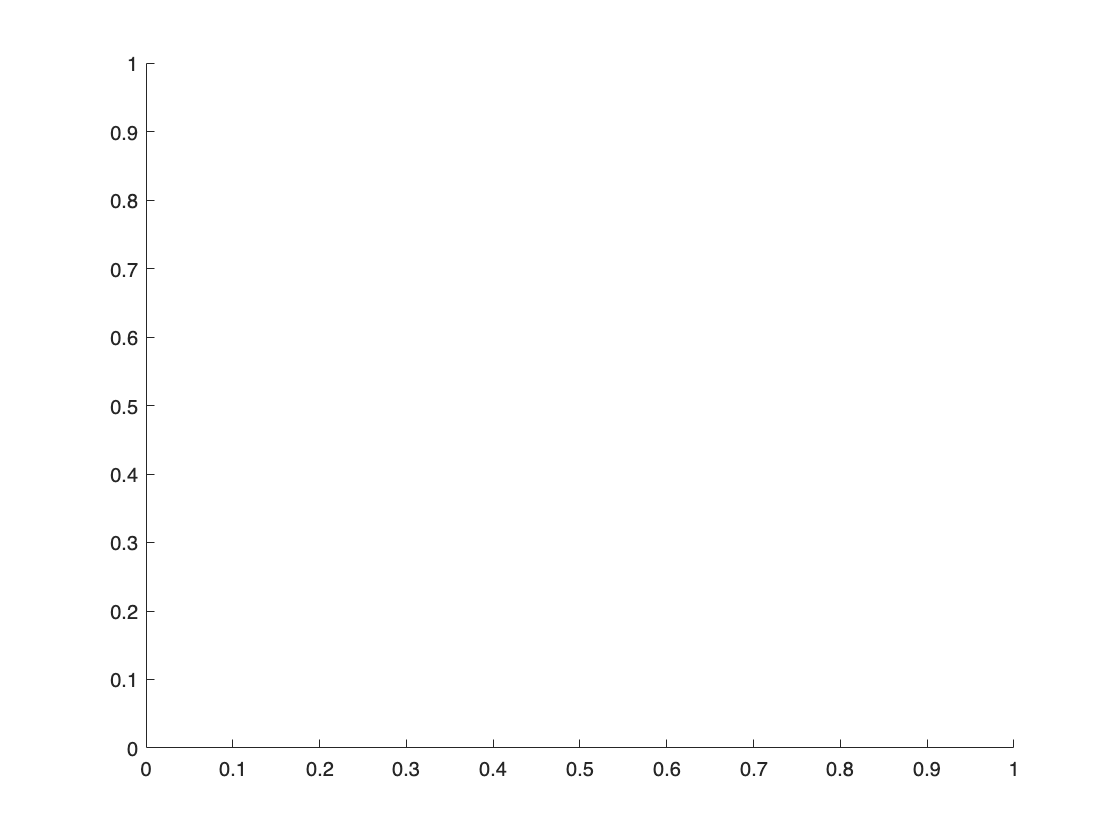

Error using msVAR/estimate
Number of series in data and model must agree.

Mdl0 = msVAR(mc0,[mdl10,mdl20]);

figure
EstMdl = estimate(Mdl0,Mdl0,data_sku(:,4:7),'X',data_sku,'IterationPlot',true);